# Welch's Method

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

load ./data/psdsig.mat
whos

  Name         Size            Bytes  Class     Attributes

  fr           1x1                 8  double              
  fs           1x1                 8  double              
  n            1x1                 8  double              
  sig       2400x1             19200  double              
  t         2400x1             19200  double              



## Task 1

The first three inputs to `pwelch` are the same as `periodogram`, although they can behave differently. You'll explore the differences in this lesson.

w = ones(n, 1);
nfft = 2^12; 

## Task 2

As you saw in the video, you can overlap the windowed segments when you're using `pwelch`. For now, since your window is the length of your signal, you'll set the number of samples to overlap to 0.

numoverlap = 0;

## Task 3

The order of inputs to `pwelch` is

- Signal

- Window

- Number of overlap samples

- Number of DFT points

- Sample rate

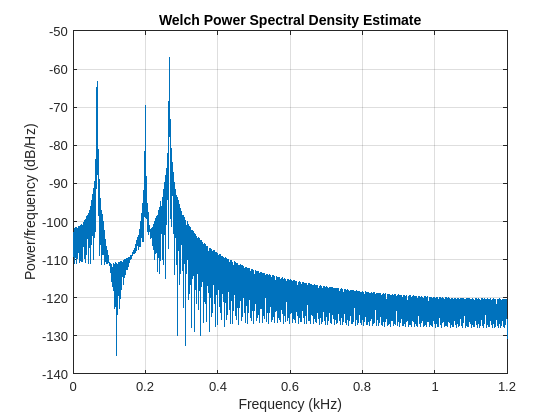

pwelch(sig, w, numoverlap, nfft, fs)

## Task 4

You can use the default values for any input by using an empty array (`[]`).

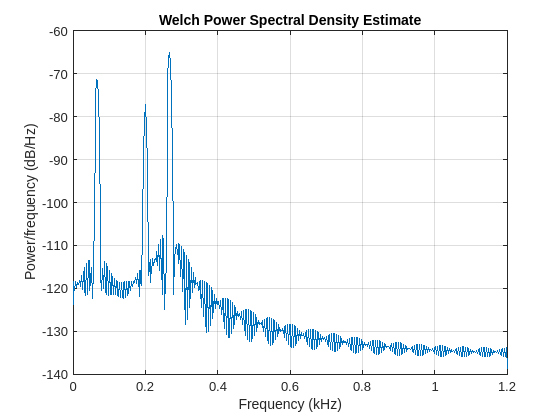

pwelch(sig, [], [], [], fs)